## Чтение файла "proto.txt"

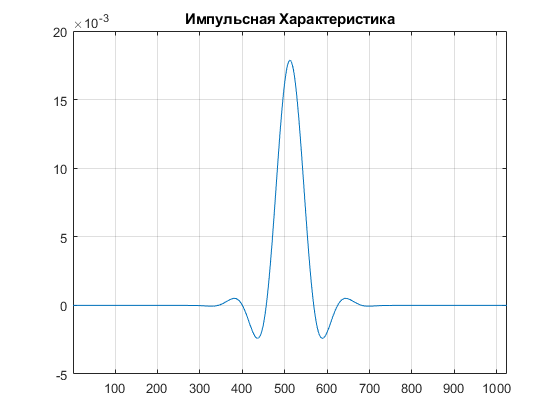

clear all;
clc;
text = fopen('proto.txt');
k = 0;
while ~feof(text)
    tline = fgetl(text);
    h(k + 1) = str2double(tline);
    k = k + 1;
end
fclose(text);
plot(1:length(h), h); title('Импульсная Характеристика');
grid on; xlim([1, length(h)]); ylim([-5*(10^-3), 20*(10^-3)]);

clear tline text k;

## Исходные данные

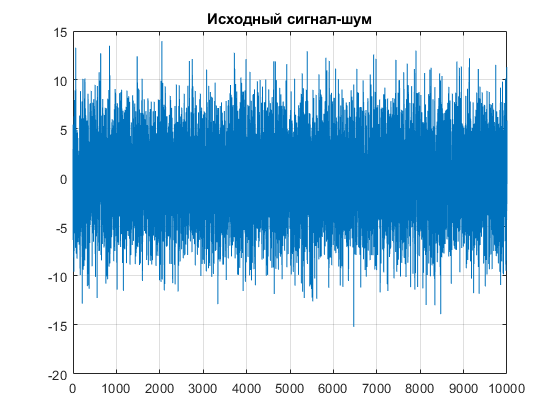

L = 32;
Fs = 1000;
f0 = 50;
T = 1 / Fs;
max = 10000;
t = (0 : (max-1))*T;
x = awgn(sin(2*pi*f0*t), -15,'measured');
plot(real(x)); title('Исходный сигнал-шум'); grid on; xlim([0, 10000]); % ylim([-7,7]);

clear max t;

## Complex modulated filter bank

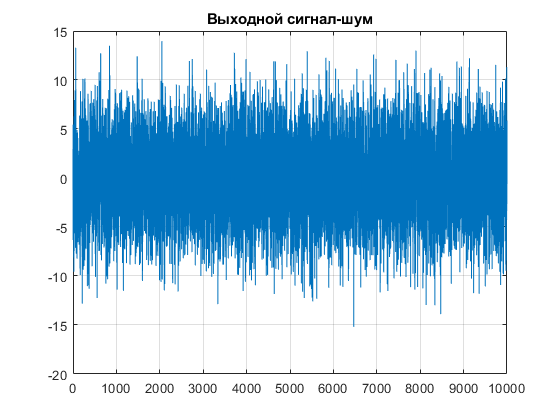

h_copy = h; x_copy = x;
N = length(h_copy);
for (k = 1 : 2*L)
    for (n = 1 : N)
        hk(k, n) = h_copy(n)*exp(1i*(2*pi*(k-1)/(2*L))*((n-1)-((N-1)/2)));
    end
end
for (k = 1 : 2*L)
    gap_1(k, :) = conv(x_copy, hk(k, :));
    gap_2(k, :) = downsample(gap_1(k, :), L);
    gap_3(k, :) = upsample(gap_2(k, :), L);
    gap_4(k, :) = conv(gap_3(k, :), hk(k, :));
end

for (n = 1 : size(gap_4, 2))
    y(n) = sum(gap_4(:, n));
end
% length(y)
y(1:length(h)-1) = [];
y((length(x)+1) : end) = [];
y(:)=y(:)*L;
plot(real(y)); title('Выходной сигнал-шум');
grid on; xlim([0, 10000]); %ylim([-7,7]);

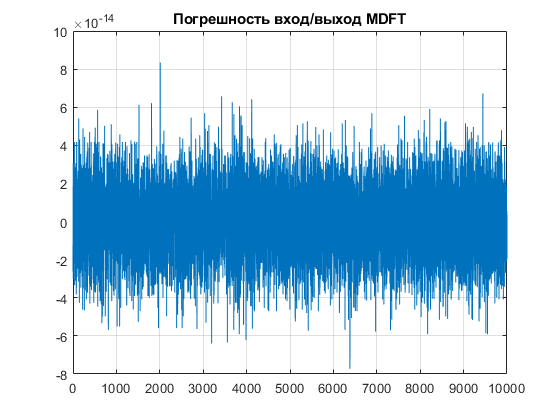

for (n = 1 : length(x))
    dif(n) = real(x(n)) - real(y(n));
end
% x(1) y(1) dif(1)
plot(1:length(dif), dif); title('Погрешность вход/выход MDFT'); grid on;

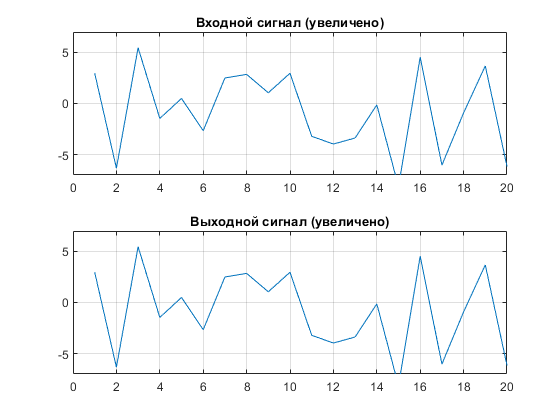

figure 
subplot(2,1,1);
plot(1:length(x), real(x)); title('Входной сигнал (увеличено)');
grid on; xlim([0, 20]); ylim([-7,7]);
subplot(2,1,2);
plot(1:length(y), real(y)); title('Выходной сигнал (увеличено)');
grid on; xlim([0, 20]); ylim([-7,7]);

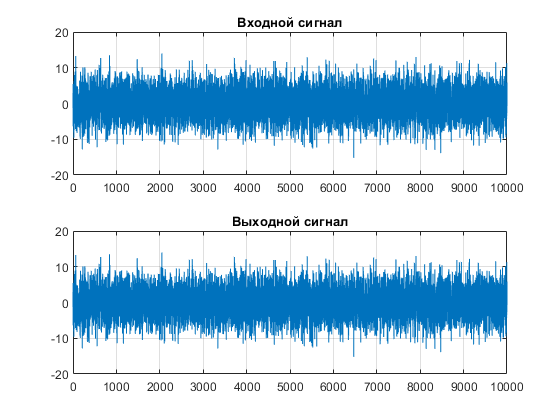


figure 
subplot(2,1,1); 
plot(1:length(x), real(x)); title('Входной сигнал'); grid on;
subplot(2,1,2);
plot(1:length(y), real(y)); title('Выходной сигнал'); grid on;